w = 0.5

w = 0.5000

sine = tf([w], [1 0 w])

sine =
 
     0.5
  ---------
  s^2 + 0.5
 
Continuous-time transfer function.



scale_factor = 1/dcgain(sine)

scale_factor = 1

sine = scale_factor*sine

sine =
 
     0.5
  ---------
  s^2 + 0.5
 
Continuous-time transfer function.



[stepresp, t] = step(sine, 100)

stepresp =          0
    0.0490
    0.1911
    0.4125
    0.6914
    1.0006
    1.3096
    1.5884
    1.8095
    1.9514


t =          0
    0.4444
    0.8889
    1.3333
    1.7778
    2.2222
    2.6667
    3.1111
    3.5556
    4.0000


a = 0.2

a = 0.2000

force = tf([1], [1 a])

force =
 
     1
  -------
  s + 0.2
 
Continuous-time transfer function.



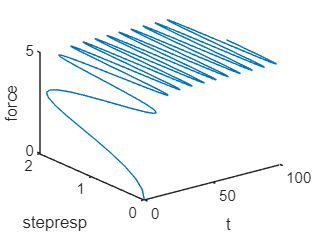

plot3(t, stepresp, step(force,t))
xlabel("t")
ylabel("stepresp")
zlabel("force")

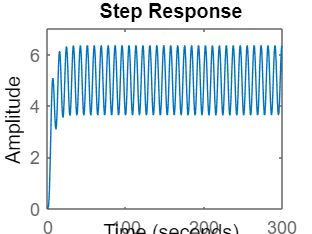

step(sine*force, 300)

## Trial for cylinder

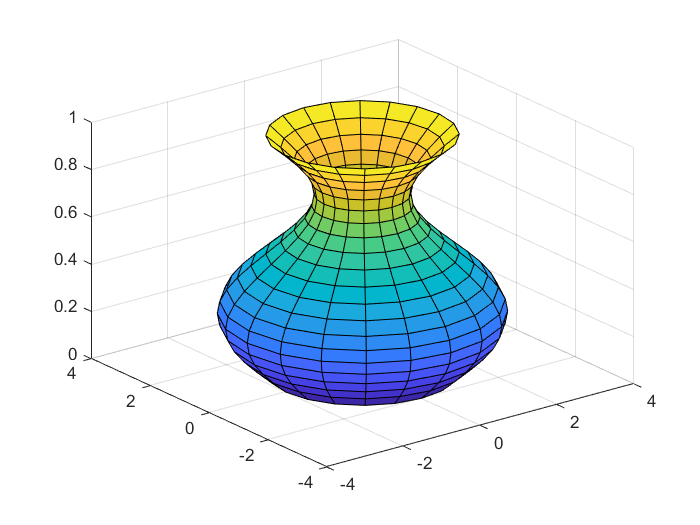

zcyl= 0:pi/10:2*pi;
figure
% how do I apply a forcing function to z?
r1cyl = 2 + 1*sin(zcyl) ;

%if r<0 do something?
[Xcyl,Ycyl,Zcyl] = cylinder(r1cyl);
surf(Xcyl,Ycyl,Zcyl)


%could make a tf for each coordinate?
%make eavh pt spin & add a F to each r pt?


## Trial 2

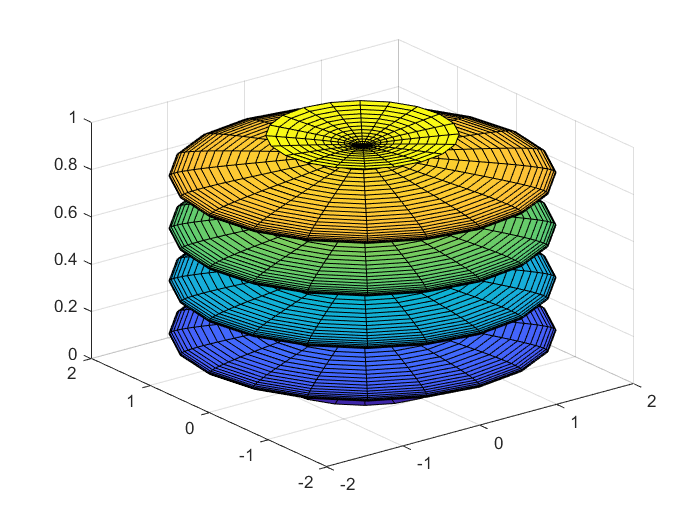

 z = 0:pi/30:9*pi;
 rad_force = sin(z);
 r = 1 - sin(z);
 [X,Y,Z] = cylinder(r);
 surf(X,Y,Z)

 hold on
 X_circle 

 


## Trial for TF for r

figure
 wn = 0.05

wn = 0.0500

z = 0.5

z = 0.5000

tfr = tf([wn], [1 2*z*wn wn^2]);
step1 = linspace(0,400,600);
[r, t] = step(tfr, step1);
a_axis= 5*r;
b_axis = 2*5*dcgain(tfr) - a_axis

b_axis =   200.0000
  199.9449
  199.7820
  199.5151
  199.1478
  198.6839
  198.1271
  197.4809
  196.7491
  195.9353


plot(t, r)
hold on
stepinfo(tfr);
dcgain(tfr);
b = 2*dcgain(tfr) - r

b =    40.0000
   39.9890
   39.9564
   39.9030
   39.8296
   39.7368
   39.6254
   39.4962
   39.3498
   39.1871


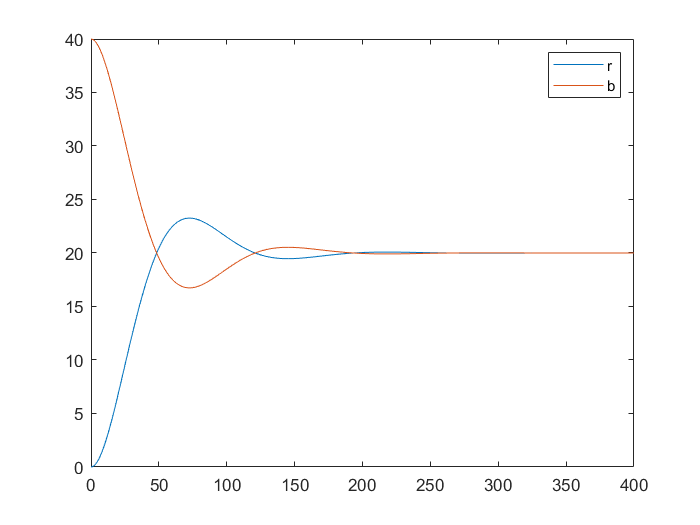

plot(t, b)
legend("r", "b")

figure
plot(t, a_axis)
hold on
b = 2*dcgain(tfr) - r

b =    40.0000
   39.9890
   39.9564
   39.9030
   39.8296
   39.7368
   39.6254
   39.4962
   39.3498
   39.1871


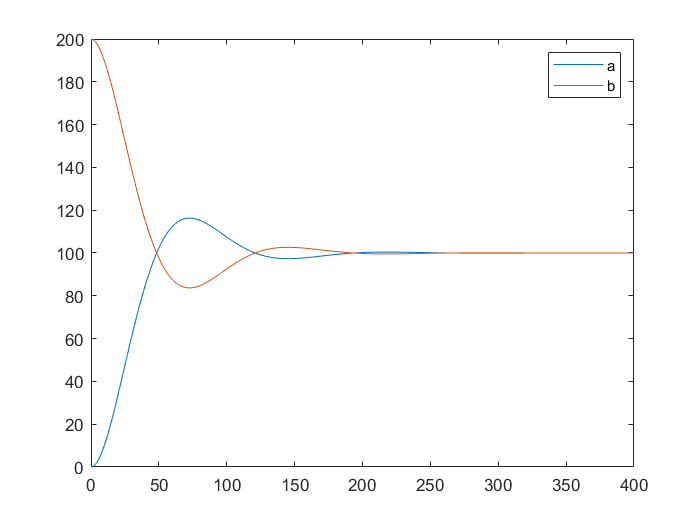

plot(t, b_axis)
legend("a", "b")

## Trial for an animation

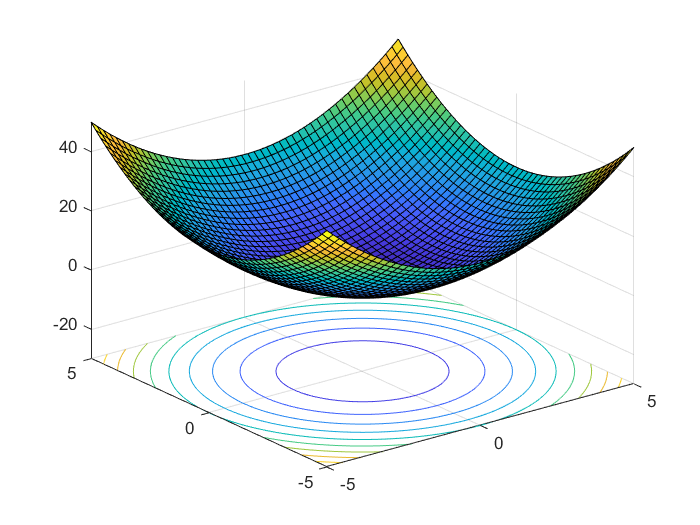

[X,Y] = meshgrid(linspace(-5, 5, 50));
fcn = @(x,y,k) k*x.^2 + y.^2;
v = [1:-0.05:-1;  -1:0.05:1];
for k1 = 1:2
    for k2 = v(k1,:)
        surfc(X, Y, fcn(X,Y,k2))
        axis([-5  5    -5  5    -30  50])
        drawnow
        pause(0.1)
    end
end

## Trying out making a cylinder

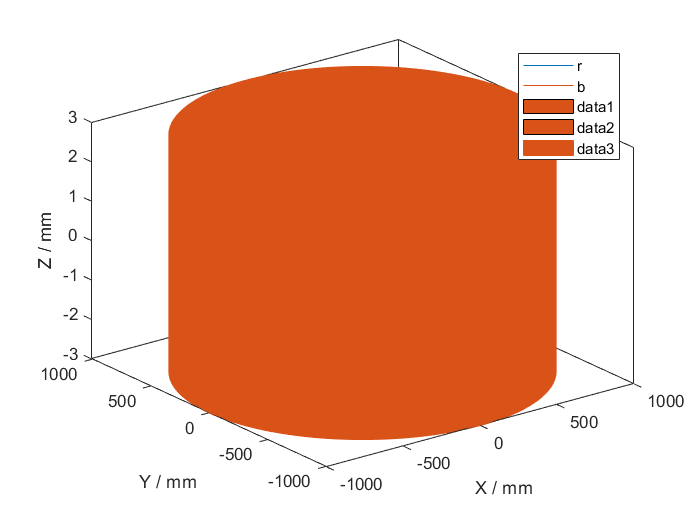

%% Some random parameters
a_fit=1000;
b_fit=1010;
%% create samples and apply to the ellipcital equation
samples=1000;
samp_theta=linspace(0,2*pi,samples);
samp_r=sqrt(1./((cos(samp_theta')).^2./a_fit.^2+(sin(samp_theta')).^2./b_fit.^2));
[samp_X,samp_Y] = pol2cart(samp_theta',samp_r);
samp_Z_1=repmat(-3,samples,1);
samp_Z_2=repmat(3,samples,1);
%% visualize
figure(1);
hold on
patch('XData',samp_X,'YData',samp_Y,'ZData',samp_Z_1,'FaceColor',[0.8500, 0.3250, 0.0980]);
patch('XData',samp_X,'YData',samp_Y,'ZData',samp_Z_2,'FaceColor',[0.8500, 0.3250, 0.0980]);
% This is new. I define the vertices using the existing variables
% The data is transposed so that they are 4xSamples
lX = [samp_X samp_X samp_X samp_X]'; 
lY = [samp_Y samp_Y samp_Y samp_Y]'; 
lZ = [samp_Z_1 samp_Z_2 samp_Z_2 samp_Z_1]'; 
% circshift the X and Y values to allow for my vertex numbering scheme
lX(3:4,:)=circshift(lX(3:4,:),-1,2);
lY(3:4,:)=circshift(lY(3:4,:),-1,2);
patch('XData',lX,'YData',lY,'ZData',lZ,'FaceColor',[0.8500, 0.3250, 0.0980],'EdgeColor',[0.8500, 0.3250, 0.0980]);
hold off
xlabel('X / mm');
ylabel('Y / mm');
zlabel('Z / mm'); 
view(3)

## another method

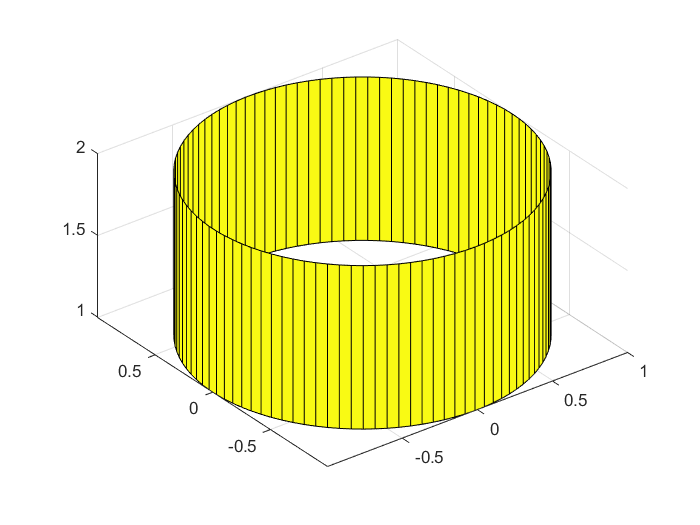

a = linspace(0, 2*pi);
crcl = [cos(a); sin(a)];
figure
surf([crcl(1,:); crcl(1,:)], [crcl(2,:); crcl(2,:)], [2*ones(size(a)); ones(size(a))])
axis equal

## to make rotating rim

%% rim (THIS ONE WORKS*****) 

wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,1200,600);
[r, t] = step(tfr, step1);
%r = r*4;
a = r;
c = 2*dcgain(tfr) - r;
figure
hAx = axes('XLim',[-250 250], 'YLim',[-250 250], ...
    'Drawmode','fast', 'NextPlot','add');

axis(hAx, 'equal')

p = calculateEllipse(0, 0, a(1), c(1), step1(1));
hLine = line('XData',p(:,1), 'YData',p(:,2), 'EraseMode','xor',  ...
    'Color','r', 'LineWidth',3);


for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
    set(hLine,'XData',p(:,1), 'YData',p(:,2))  %# update X/Y data
%     pause(.10)                                 %# slow down animation
    drawnow                                    %# force refresh
    if ~ishandle(hLine), return; end           %# in case you close the figure
end



## first lets make a 3d cylinder with the ellipse

%a = linspace(0, 2*pi);
%crcl = [cos(a); sin(a)];
[xx, yy] = calculateEllipse(0, 0, a(20), c(20), step1(20))
figure
surf([xx; xx], [yy; yy], [2*ones(36); ones(36)])
axis equal


## playing around with cylinder

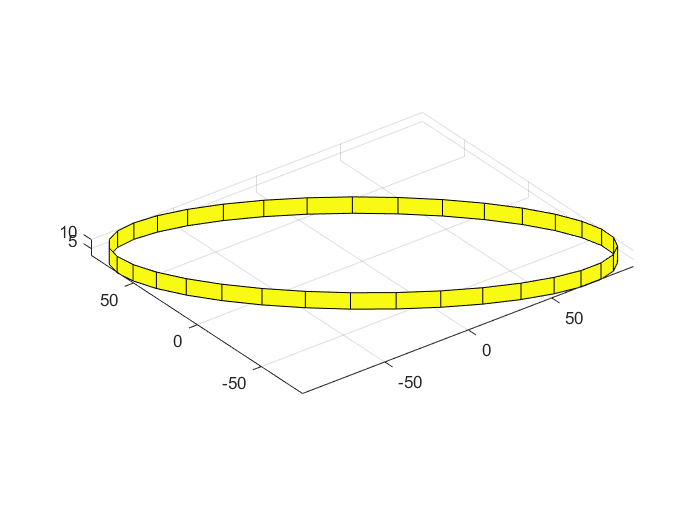

% aa = linspace(0, 2*pi);
% crcl = [cos(aa); sin(aa)];
p = calculateEllipse(0, 0, a(20), c(20), step1(20));
figure
surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])
axis equal

## now time to put it all together

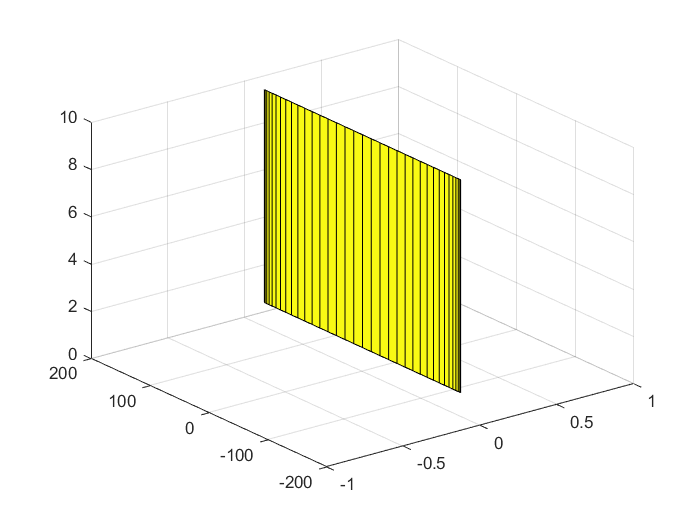

figure
wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,1200,600);
[r, t] = step(tfr, step1);
%r = r*4;
a = r;
c = 2*dcgain(tfr) - r;
figure
%  hAx = axes('XLim',[-250 250], 'YLim',[-250 250],'ZLim', [0, 11], ...
%      'Drawmode','fast', 'NextPlot','add');
%  axis(hAx, 'equal')

p = calculateEllipse(0, 0, a(1), c(1), step1(1));
% hLine = line('XData',p(:,1), 'YData',p(:,2), 'EraseMode','xor',  ...
%     'Color','r', 'LineWidth',3);
surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])

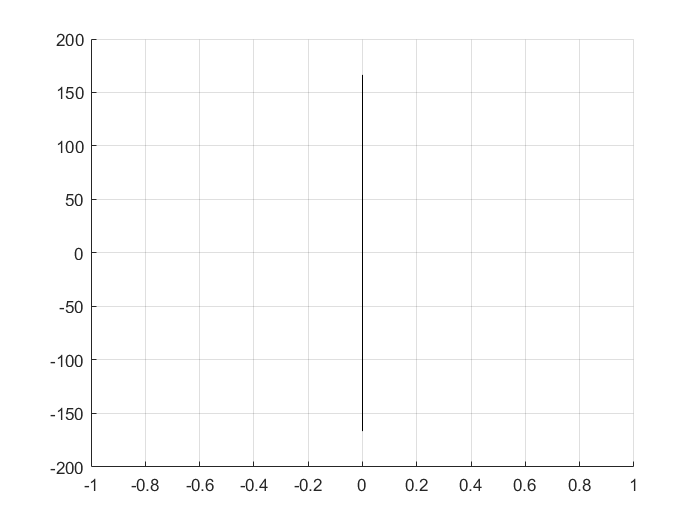

Unrecognized function or variable 'hLine'.


for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
%     set(hLine,'XData',p(:,1), 'YData',p(:,2))  %# update X/Y data
% %     pause(.10)                                 %# slow down animation
    surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])
    view(2)
    drawnow                                    %# force refresh
    if ~ishandle(hLine), return; end           %# in case you close the figure
end

## now time to put it all together

figure
wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,1200,600);
[r, t] = step(tfr, step1);
%r = r*4;
a = r;
c = 2*dcgain(tfr) - r;
figure
%  hAx = axes('XLim',[-250 250], 'YLim',[-250 250],'ZLim', [0, 11], ...
%      'Drawmode','fast', 'NextPlot','add');
%  axis(hAx, 'equal')

p = calculateEllipse(0, 0, a(1), c(1), step1(1));
% hLine = line('XData',p(:,1), 'YData',p(:,2), 'EraseMode','xor',  ...
%     'Color','r', 'LineWidth',3);
surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])

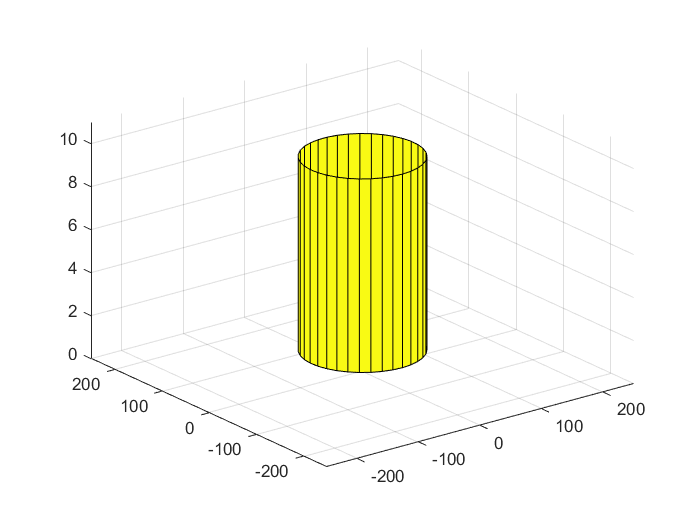


for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
%     set(hLine,'XData',p(:,1), 'YData',p(:,2))  %# update X/Y data
% %     pause(.10)                                 %# slow down animation
    surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])
    axis([-250 250 -250 250 0 11])
    drawnow                                    %# force refresh
    if ~ishandle(hLine), return; end           %# in case you close the figure
end

## set axis properly

figure

wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,1200,600);
[r, t] = step(tfr, step1);
%r = r*4;
a = r;
c = 2*dcgain(tfr) - r;
figure
%  hAx = axes('XLim',[-250 250], 'YLim',[-250 250],'ZLim', [0, 11], ...
%      'Drawmode','fast', 'NextPlot','add');
%  axis(hAx, 'equal')

p = calculateEllipse(0, 0, a(1), c(1), step1(1));
% hLine = line('XData',p(:,1), 'YData',p(:,2), 'EraseMode','xor',  ...
%     'Color','r', 'LineWidth',3);
surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])


for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
%     set(hLine,'XData',p(:,1), 'YData',p(:,2))  %# update X/Y data
% %     pause(.10)                                 %# slow down animation
    surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])
    axis([-250 250 -250 250 0 11])
    drawnow                                    %# force refresh
    if ~ishandle(hLine), return; end           %# in case you close the figure
end

## try making it pot shaped

figure

wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,1200,600);
[r, t] = step(tfr, step1);
%r = r*4;
a = r;
c = 2*dcgain(tfr) - r;
figure
%  hAx = axes('XLim',[-250 250], 'YLim',[-250 250],'ZLim', [0, 11], ...
%      'Drawmode','fast', 'NextPlot','add');
%  axis(hAx, 'equal')

p = calculateEllipse(0, 0, a(1), c(1), step1(1));
% hLine = line('XData',p(:,1), 'YData',p(:,2), 'EraseMode','xor',  ...
%     'Color','r', 'LineWidth',3);
surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])

for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
%     set(hLine,'XData',p(:,1), 'YData',p(:,2))  %# update X/Y data
% %     pause(.10)                                 %# slow down animation
    surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])
    axis([-250 250 -250 250 0 11])
    drawnow                                    %# force refresh
    if ~ishandle(hLine), return; end           %# in case you close the figure
end

% g= linspace(0, 2*pi, 36)'
% h = repmat(g,1,36)
% surf([p(:,1).*sin(g)'; p(:,1).*sin(g)'], [p(:,2).*sin(g)'; p(:,2).*sin(g)'],h)

g =          0
    0.1795
    0.3590
    0.5386
    0.7181
    0.8976
    1.0771
    1.2566
    1.4362
    1.6157


## This makes a pot shaped thingy

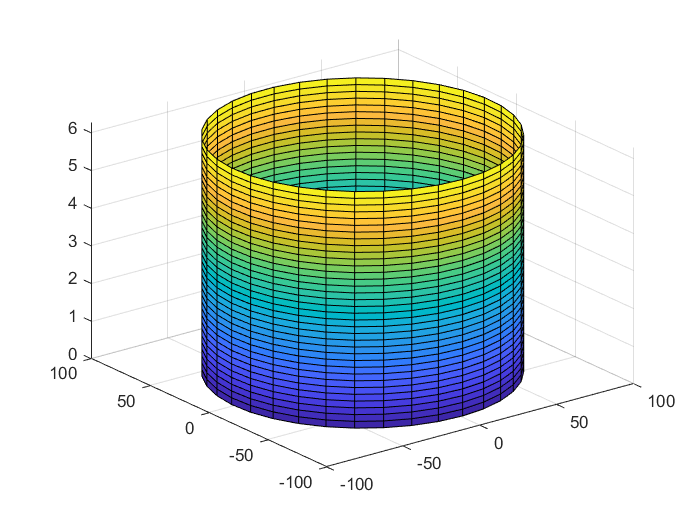


figure
g= linspace(0, 2*pi, 36)';
h = repmat(g,1,36)';
xtrial = repmat(p(:,1), 1, 36);
ytrial = repmat(p(:,2), 1, 36);
for i = 1:length(g)
    xtrial2(:,i) = xtrial(:,i)*(sin(g(i)*0.7)+2);
    ytrial2(:,i) = ytrial(:,i)*(sin(g(i)*0.7)+2);
end 
xtrial2; 
ytrial2;
surf(xtrial, ytrial,h)

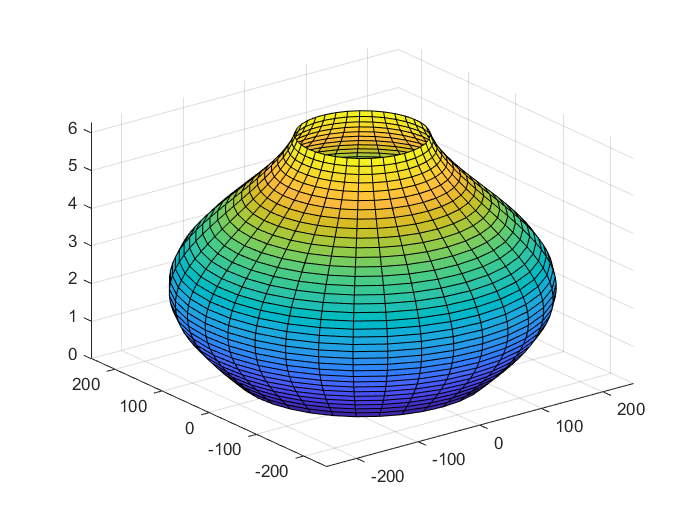

surf(xtrial2, ytrial2,h)

## Put it all together!!

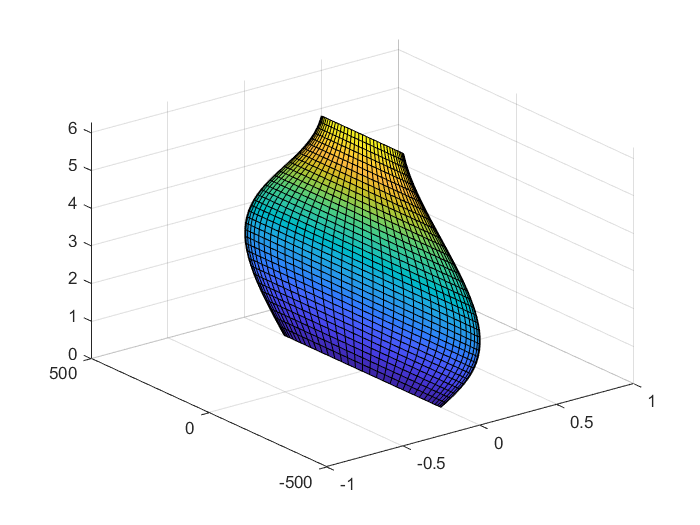

figure
%% transfer function for major axis'
wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,400,600);
[r, t] = step(tfr, step1);
a = r;
c = 2*dcgain(tfr) - a;

%%calculate elipse coordinates
p = calculateEllipse(0, 0, a(1), c(1), step1(1));

%%make into a surf matrix

g= linspace(0, 2*pi, 36)';
h = repmat(g,1,36)';
xtrial = repmat(p(:,1), 1, 36);
ytrial = repmat(p(:,2), 1, 36);
for i = 1:length(g)
    xtrial2(:,i) = xtrial(:,i)*(sin(g(i)*0.7)+2);
    ytrial2(:,i) = ytrial(:,i)*(sin(g(i)*0.7)+2);
end 

%% first plot
surf(xtrial2, ytrial2,h)

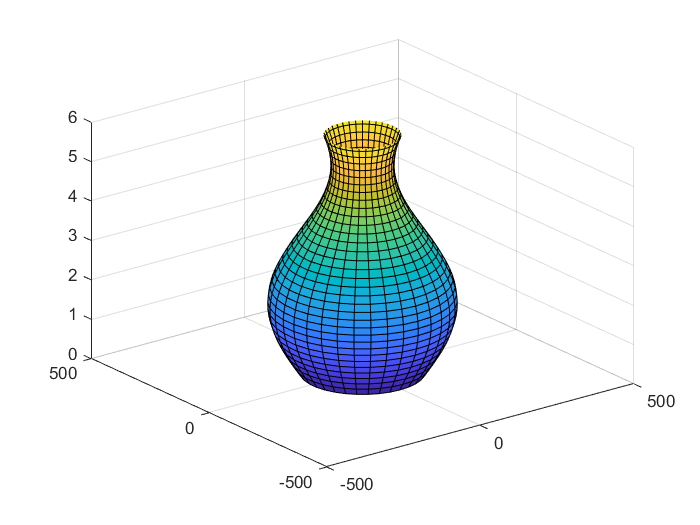


%%animation: update for every t
for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
    xtrial = repmat(p(:,1), 1, 36);
    ytrial = repmat(p(:,2), 1, 36);
    for j = 1:length(g)
        xtrial2(:,j) = xtrial(:,j)*(sin(g(j)*0.9)+2);
        ytrial2(:,j) = ytrial(:,j)*(sin(g(j)*0.9)+2);
    end 
    surf(xtrial2, ytrial2,h)
    axis([-500 500 -500 500 0 6])
    drawnow                                    %# force refresh
    %if ~ishandle(hLine), return; end           %# in case you close the figure
end

## Try some other tf's

figure
%% transfer function for major axis'
wn = 0.06;
z = -0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,400,400);
[r, t] = step(tfr, step1);
a = r;
c = 2*dcgain(tfr) - a;

%%calculate elipse coordinates
p = calculateEllipse(0, 0, a(1), c(1), step1(1));

%%make into a surf matrix

g= linspace(0, 2*pi, 36)';
h = repmat(g,1,36)';
xtrial = repmat(p(:,1), 1, 36);
ytrial = repmat(p(:,2), 1, 36);
for i = 1:length(g)
    xtrial2(:,i) = xtrial(:,i)*(sin(g(i)*0.7)+2);
    ytrial2(:,i) = ytrial(:,i)*(sin(g(i)*0.7)+2);
end 

%% first plot
surf(xtrial2, ytrial2,h)


%%animation: update for every t
for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
    xtrial = repmat(p(:,1), 1, 36);
    ytrial = repmat(p(:,2), 1, 36);
    for j = 1:length(g)
        xtrial2(:,j) = xtrial(:,j)*(sin(g(j)*0.5)+2);
        ytrial2(:,j) = ytrial(:,j)*(sin(g(j)*0.5)+2);
    end 
    surf(xtrial2, ytrial2,h)
    axis([-500 500 -500 500 0 6])
    drawnow                                    %# force refresh
    %if ~ishandle(hLine), return; end           %# in case you close the figure
end

## other tf's

## Try some other tf's

figure
%% transfer function for major axis'
wn = 0.06;
z = -0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,400,400);
[r, t] = step(tfr, step1);
a = r;
c = 2*dcgain(tfr) - a;

%%calculate elipse coordinates
p = calculateEllipse(0, 0, a(1), c(1), step1(1));

%%make into a surf matrix

g= linspace(0, 2*pi, 36)';
h = repmat(g,1,36)';
xtrial = repmat(p(:,1), 1, 36);
ytrial = repmat(p(:,2), 1, 36);
for i = 1:length(g)
    xtrial2(:,i) = xtrial(:,i)*(sin(g(i)*0.7)+2);
    ytrial2(:,i) = ytrial(:,i)*(sin(g(i)*0.7)+2);
end 

%% first plot
surf(xtrial2, ytrial2,h)

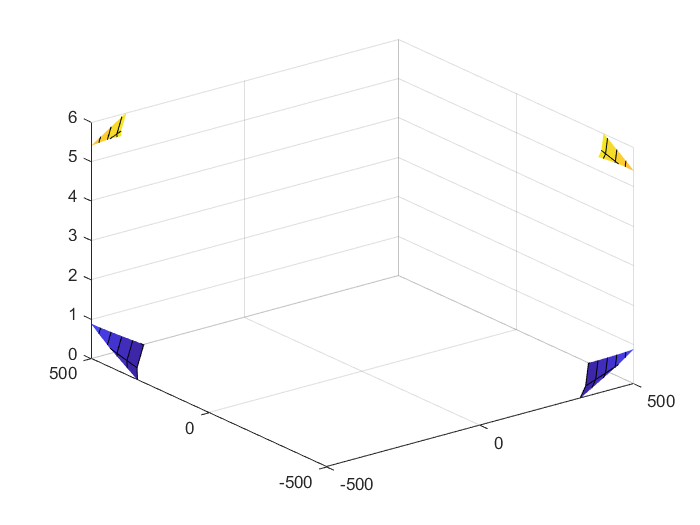


%%animation: update for every t
for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
    xtrial = repmat(p(:,1), 1, 36);
    ytrial = repmat(p(:,2), 1, 36);
    for j = 1:length(g)
        xtrial2(:,j) = xtrial(:,j)*(sin(g(j)*0.5)+2);
        ytrial2(:,j) = ytrial(:,j)*(sin(g(j)*0.5)+2);
    end 
    surf(xtrial2, ytrial2,h)
    axis([-500 500 -500 500 0 6])
    drawnow                                    %# force refresh
    %if ~ishandle(hLine), return; end           %# in case you close the figure
end